% =========================================================================
% UNIVERSIDAD NACIONAL DEL CHIMBORAZO (UNACH)
% Facultad de Ingeniería - Ciencia de Datos e IA
% Proyecto: Predicción de Precios de Bienes Raíces mediante Álgebra Lineal
% =========================================================================

clear; clc; close all;

% --- PASO 1: Carga de Datos (Fuente: Index Plusvalía/Properati 2026) ---
% x: Metros cuadrados de construcción
% y: Precio de venta en miles de USD
x = [65; 82; 105; 120; 155; 190; 210]; 
y = [98; 125; 158; 185; 230; 295; 320];

% --- PASO 2: Creación de la Matriz de Diseño (X) ---
% Se concatena columna de unos (intercepto) con los datos de x
n = length(x);
X = [ones(n, 1), x];

disp('--- ESTRUCTURA DE LA MATRIZ DE DISEÑO X ---');

--- ESTRUCTURA DE LA MATRIZ DE DISEÑO X ---


disp(X);

     1    65
     1    82
     1   105
     1   120
     1   155
     1   190
     1   210




% --- PASO 3: Aplicación de la Ecuación Normal (Álgebra Lineal) ---
% Operación matricial: beta = (X' * X)^-1 * X' * y
beta = inv(X' * X) * X' * y;

% --- PASO 4: Generación de Predicciones e Inferencias ---
% Aplicamos los pesos hallados (beta) a nuestra matriz original
y_pred = X * beta;

% --- PASO 5: Análisis de Resultados y Tabla Comparativa ---
error_residual = y - y_pred;
TablaResultados = table(x, y, y_pred, error_residual, ...
    'VariableNames', {'Metros_m2', 'Precio_Real', 'Precio_Predicho', 'Error_kUSD'});

fprintf('\n--- COMPARATIVA: REAL VS. PREDICHO ---\n');


--- COMPARATIVA: REAL VS. PREDICHO ---


disp(TablaResultados);

    Metros_m2    Precio_Real    Precio_Predicho    Error_kUSD
    _________    ___________    _______________    __________

        65            98            97.795           0.20509 
        82           125            123.96            1.0411 
       105           158            159.36           -1.3573 
       120           185            182.44            2.5569 
       155           230            236.31           -6.3102 
       190           295            290.18            4.8228 
       210           320            320.96          -0.95839 




% --- PASO 6: Evaluación Global del Modelo (Métricas de Ingeniería) ---
SS_res = sum((y - y_pred).^2);           % Suma de residuos al cuadrado
SS_tot = sum((y - mean(y)).^2);          % Variación total de los datos
R2 = 1 - (SS_res / SS_tot);              % Coeficiente de Determinación

fprintf('\n--- MÉTRICAS DE RENDIMIENTO ---\n');


--- MÉTRICAS DE RENDIMIENTO ---


fprintf('Intercepto (Beta 0): %.4f\n', beta(1));

Intercepto (Beta 0): -2.2439


fprintf('Pendiente (Beta 1): %.4f (Precio/m2)\n', beta(2));

Pendiente (Beta 1): 1.5391 (Precio/m2)


fprintf('Precisión del Modelo (R^2): %.4f (%.2f%%)\n', R2, R2*100);

Precisión del Modelo (R^2): 0.9983 (99.83%)


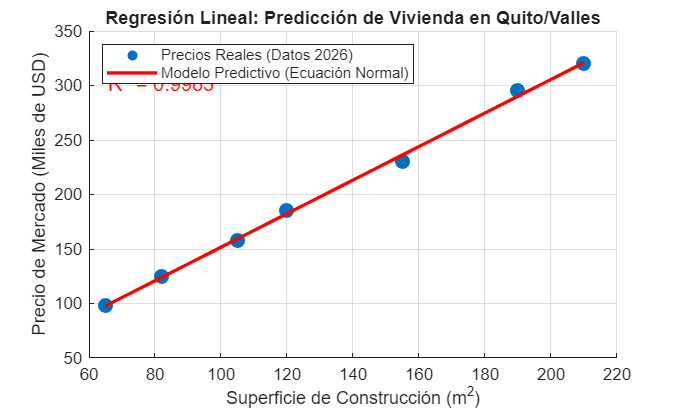


% --- PASO 7: Visualización Gráfica Final ---
figure('Color', 'w');
scatter(x, y, 80, 'filled', 'MarkerFaceColor', [0 0.447 0.741]); 
hold on;
plot(x, y_pred, 'r-', 'LineWidth', 2); 
grid on;

% Estética del gráfico
title('Regresión Lineal: Predicción de Vivienda en Quito/Valles');
xlabel('Superficie de Construcción (m^2)');
ylabel('Precio de Mercado (Miles de USD)');
legend('Precios Reales (Datos 2026)', 'Modelo Predictivo (Ecuación Normal)', ...
       'Location', 'northwest');

% Anotación del R^2 en el gráfico
text(min(x), max(y)-20, sprintf('R^2 = %.4f', R2), 'FontSize', 12, 'Color', 'r');


% --- PASO 8: Predicción de un nuevo valor (Ejemplo: Casa de 300m2) ---
m2_nuevo = 300;
precio_estimado = beta(1) + beta(2)*m2_nuevo;
fprintf('\n--- PREDICCIÓN EXTRA ---\n');


--- PREDICCIÓN EXTRA ---


fprintf('Una propiedad de %d m2 costaría aprox: $%.2f USD\n', m2_nuevo, precio_estimado*1000);

Una propiedad de 300 m2 costaría aprox: $459473.66 USD
